# **LGBeam 用于计算LG光束场振幅的分布**

[`LGbeam(p, l, w, z, lambda, r, phi)`](matlab:open('..\optics\LGBeam.m')) 是一个复数标量函数，描述了满足准轴近似下的波动方程并受以下参数限制的拉盖尔-高斯光束场振幅分布：

clc;
clear;
p = 0;                 % 径向量子数
l = 0;                 % 角向量子数
w_0 = 0.0005;            % 光束束腰尺寸
z = 0;         % 传播距离
lambda =  5e-7 ;       % 光束波长
L = 10e-3;
N = 1000;
xoy = linspace(-0.5 * L, 0.5 * L, N);
[X, Y] = meshgrid(xoy, xoy);
[phi, r] = cart2pol(X, Y);             % 获取柱坐标系下，半径 r 和角度 phi

拉盖尔-高斯光束场振幅分布[[1]](https://en.wikipedia.org/wiki/Gaussian_beam#Laguerre-Gaussian_modes)通过以下公式得到: 


$$u(r, \phi, z) = C_{l p}^{L G} \frac{1}{w(z)}\left(\frac{r \sqrt{2}}{w(z)}\right)^{|l|} \exp \left(-\frac{r^{2}}{w^{2}(z)}\right) L_{p}^{|l|}\left(\frac{2 r^{2}}{w^{2}(z)}\right) 
 \exp \left(-i k \frac{r^{2}}{2 R(z)}\right) \exp (-i l \phi) \exp (i \psi(z))$$


其中， $C_{l p}^{L G}$ 是`归一化常数，由 `$\int_{0}^{2 \pi} d \phi \int_{0}^{\infty} r d r|u(r, \phi, z)|^{2}=1$得到：$C_{l p}^{L G}=\sqrt{\frac{2 p !}{\pi(p+|l|) !}}$

$w(z)$ 是[光束尺寸](https://en.wikipedia.org/wiki/Gaussian_beam#Beam_waist)，并由 $w(z)=w_{0} \sqrt{1+\left(\frac{z}{z_{\mathrm{R}}}\right)^{2}}$得到，

其中 $z_{\mathrm{R}}$ 是瑞利范围，并由 $z_{\mathrm{R}}=\frac{\pi w_{0}^{2} n}{\lambda}$ 得到。其中，$w_0$ 是光束束腰尺寸， $n$ 为介质折射率， $\lambda$ 是光波长。

$ L_{p}^{|l|}(x)$ 是[广义拉盖尔多项式](https://en.wikipedia.org/wiki/Laguerre_polynomials#Generalized_Laguerre_polynomials)，可以使用 [`laguerre(p, `$|l|$`, x)`](matlab:open('..\common\laguerre.m')) 得到。

$R(z)$ 是[波前曲率](https://en.wikipedia.org/wiki/Gaussian_beam#Wavefront_curvature)，由 $R(z)=z\left[1+\left(\frac{z_{\mathrm{R}}}{z}\right)^{2}\right]$ 得到。

$\psi(z)$是[***Gouy ***相位](https://en.wikipedia.org/wiki/Gaussian_beam#Gouy_phase)，是光波经过其束腰时产生的轴向相移，由 $\psi(z)=\arctan \left(\frac{z}{z_{\mathrm{R}}}\right)$ 得到。

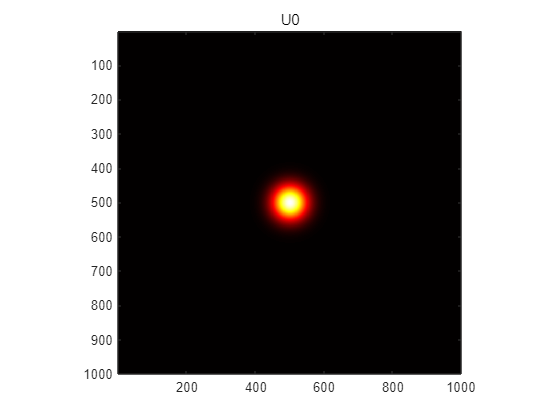

U0 = LGBeam(p,l,w_0,z,lambda,r,phi);   % 得到光强分布

figure                                 % 绘制光场分布图
imagesc(abs(U0))
title("U0")
colormap hot
axis square

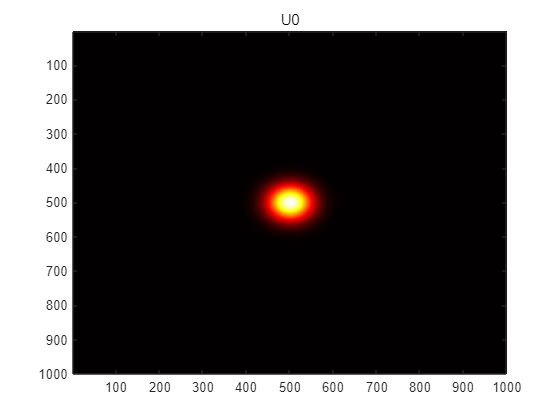

% 创建 U0 的 imagesc
im = imagesc(U0);

% 添加 title
title("U0")